clearvars;

# Wind tunnel model 

u1 : flow control, u2 : temperature control

y1 : flow measure, y2 : temperature measure

## Identified model

% H_vent_mass = exp(-0.1*u1) * (1.053 * u1 + 1.155)/(u1^3 + 1.942 u1^2 + 6.112 * u1 + 1.517);
% H_vent_temp = exp(-1.7*u1) * (-0.005487 u1^2 + 0.02488 * u1 + 0.0264)/(u1^2 + 0.7964 * u1 + 0.1684);
% H_chaf_temp = exp(-0.15*u2) * (2.674 u2 + 1.017)/(u2^3 + 9.211 u2^2 + 16.95 * u2 + 3.612);
% H_chauf_mass  = 0;

num_vent_mass = [1.0534, 1.1552];
den_vent_mass = [1, 1.9421, 6.1118, 1.5175];
H_vent_mass = tf(num_vent_mass,den_vent_mass,'IODelay',0.1)

H_vent_mass =
 
                         1.053 s + 1.155
  exp(-0.1*s) * ---------------------------------
                s^3 + 1.942 s^2 + 6.112 s + 1.518
 
Continuous-time transfer function.




num_vent_temp = [-0.005487, 0.02488, 0.02640];
den_vent_temp = [1, 0.7964, 0.1684];
H_vent_temp = tf(num_vent_temp,den_vent_temp,'IODelay',1.7)

H_vent_temp =
 
                -0.005487 s^2 + 0.02488 s + 0.0264
  exp(-1.7*s) * ----------------------------------
                     s^2 + 0.7964 s + 0.1684
 
Continuous-time transfer function.




num_chauf_temp = [2.6740, 1.0174];
den_chauf_temp = [1, 9.211, 16.95, 3.612];
H_chauf_temp = tf(num_chauf_temp, den_chauf_temp,'IODelay',0.15)

H_chauf_temp =
 
                          2.674 s + 1.017
  exp(-0.15*s) * ---------------------------------
                 s^3 + 9.211 s^2 + 16.95 s + 3.612
 
Continuous-time transfer function.



H_chauf_mass = 0

H_chauf_mass = 0


% Put here the model you found in seance 1
H = [H_vent_mass H_chauf_mass; H_vent_temp H_chauf_temp]

H =
 
  From input 1 to output...
                              1.053 s + 1.155
   1:  exp(-0.1*s) * ---------------------------------
                     s^3 + 1.942 s^2 + 6.112 s + 1.518
 
                     -0.005487 s^2 + 0.02488 s + 0.0264
   2:  exp(-1.7*s) * ----------------------------------
                          s^2 + 0.7964 s + 0.1684
 
  From input 2 to output...
   1:  0
 
                               2.674 s + 1.017
   2:  exp(-0.15*s) * ---------------------------------
                      s^3 + 9.211 s^2 + 16.95 s + 3.612
 
Continuous-time transfer function.



% sys = ss(H)
% A0, B0, C0, D0 = sys.A, sys.B, sys.C, sys.D;
% H_temp = [H_vent_temp, H_chauf_temp];
% num_temp = cell2mat(H_temp.Numerator)       
% den_temp = cell2mat(H_temp.Denominator)    
% 
% H_mass = [H_vent_mass, H_chauf_mass];
% num_mass = cell2mat(H_mass.Numerator)       
% den_mass = cell2mat(H_mass.Denominator) 

# Control model (discrete state space)

**choice of a sampling period **(keep the notation Te)

Te=0.1;

Hd=c2d(H,Te) % Matlab function to discretize a system

Hd =
 
  From input 1 to output...
                0.0051 z^2 + 0.0003871 z - 0.004442
   1:  z^(-1) * -----------------------------------
                z^3 - 2.768 z^2 + 2.592 z - 0.8235
 
                 -0.005487 z^2 + 0.01349 z - 0.007748
   2:  z^(-17) * ------------------------------------
                        z^2 - 1.922 z + 0.9234
 
  From input 2 to output...
   1:  0
 
                0.002892 z^3 + 0.01028 z^2 - 0.01097 z - 0.001546
   2:  z^(-2) * -------------------------------------------------
                       z^3 - 2.288 z^2 + 1.688 z - 0.3981
 
Sample time: 0.1 seconds
Discrete-time transfer function.



Change to state form, and state matrices extraction.

sysd=ss(Hd);
A=sysd.A;
B=sysd.B;
C=sysd.C;
D=sysd.D;

#### Inclusion of operating points

An *operating point* of a dynamic system specifies the initial states and root-level input signals of the model at a particular time.

Inclusion of operating points : ${u}_0(k+1)=u_{0}(k)
$ et $y_0(k+1)=y_0(k)$ 

% u_0=[5;5]
Aa= [A, -B, zeros(8,2); zeros(2,8), eye(2,2), zeros(2,2); zeros(2,10), eye(2,2)]

Aa =     2.7675   -1.2962    0.8235         0         0         0         0         0   -0.1250         0         0         0
    2.0000         0         0         0         0         0         0         0         0         0         0         0
         0    0.5000         0         0         0         0         0         0         0         0         0         0
         0         0         0    1.9218   -0.9234         0         0         0   -0.0625         0         0         0
         0         0         0    1.0000         0         0         0         0         0         0         0         0
         0         0         0         0         0    2.2875   -1.6879    0.7962         0   -0.2500         0         0
         0         0         0         0         0    1.0000         0         0         0         0         0         0
         0         0         0         0         0         0    0.5000         0         0         0         0         0
         0         0       

Ba= [B; zeros(2,2); zeros(2,2)]

Ba =     0.1250         0
         0         0
         0         0
    0.0625         0
         0         0
         0    0.2500
         0         0
         0         0
         0         0
         0         0


Ca= [C, zeros(2,2), eye(2,2)]

Ca =     0.0408    0.0015   -0.0355         0         0         0         0         0         0         0    1.0000         0
         0         0         0    0.0471   -0.0429    0.0676   -0.0634   -0.0032         0         0         0    1.0000


#### Decomposition according to observability

Obsa=obsv(Aa,Ca)

Obsa =     0.0408    0.0015   -0.0355         0         0         0         0         0         0         0    1.0000         0
         0         0         0    0.0471   -0.0429    0.0676   -0.0634   -0.0032         0         0         0    1.0000
    0.1160   -0.0707    0.0336         0         0         0         0         0   -0.0051         0    1.0000         0
         0         0         0    0.0476   -0.0435    0.0912   -0.1157    0.0538   -0.0029   -0.0169         0    1.0000
    0.1798   -0.1336    0.0955         0         0         0         0         0   -0.0196         0    1.0000         0
         0         0         0    0.0480   -0.0440    0.0929   -0.1270    0.0726   -0.0059   -0.0397         0    1.0000
    0.2303   -0.1852    0.1480         0         0         0         0         0   -0.0421         0    1.0000         0
         0         0         0    0.0483   -0.0443    0.0856   -0.1206    0.0740   -0.0089   -0.0629         0    1.0000
    0.2670   -0.2245    0

R = rank(Obsa)

R = 10

unob = length(Aa)-R

unob = 2

There are 10 observable modes 

[AO,BO,CO,TO]=obsvf(Aa,Ba,Ca);

$T0$  is the basis change matrix (useful for Simulink later)

We get only the observable part

Ao=AO(3:12,3:12);
Bo=BO(3:12,1:2);
Co=CO(1:2,3:12);

Eigenvalues study

eig(Ao)

ans =    0.5069 + 0.0000i
   0.8048 + 0.0000i
   0.8970 + 0.2032i
   0.8970 - 0.2032i
   0.9609 + 0.0095i
   0.9609 - 0.0095i
   0.9758 + 0.0000i
   1.0000 + 0.0000i
   0.9736 + 0.0000i
   1.0000 + 0.0000i


## State observer

Choice of the poles:

% poles_obs=[exp(-50*Te);exp(-16*Te);exp(-34*Te);exp(-20*Te);exp(-21*Te);exp(-15*Te);exp(-4*Te);exp(-3*Te);exp(-Te);exp(-45*Te)];
poles_obs = eig(Ao);

Matrice determination

L0 = place(Ao',Co',poles_obs);
L0 = L0';
eig(Ao-L0*Co);

State model of the observer (keep the following notations for simulink

% State model of the observer (keep the following notations for simulink)
A_OBS= Ao - L0*Co;
B_OBS= [Bo, L0];
C_OBS= eye(rank(Obsa));
D_OBS= zeros(rank(Obsa), 4);

# Prediction model

Choice of** the size of the prediction model**

Np=10; % keep the notation Np (required for simulink)

Explicite matrices definition

We want the following model $Y(K+1|k)=Fx(k|k)+HU(K|k)$ 

nx=size(C*A,1); 
% the row number
nu=size(C*B,2);
% the column number

F=zeros(Np*nx,8);
H=zeros(Np*nx,Np*nu);

for i=1:Np
    F(nx*(i-1)+1:nx*i,:)=C*A^i;
    for j=1:i
        H(nx*(i-1)+1:nx*i,nu*(j-1)+1:nu*j)=C*A^(i-j)*B;
    end
end

F,H

F =     0.1160   -0.0707    0.0336         0         0         0         0         0
         0         0         0    0.0476   -0.0435    0.0912   -0.1157    0.0538
    0.1798   -0.1336    0.0955         0         0         0         0         0
         0         0         0    0.0480   -0.0440    0.0929   -0.1270    0.0726
    0.2303   -0.1852    0.1480         0         0         0         0         0
         0         0         0    0.0483   -0.0443    0.0856   -0.1206    0.0740
    0.2670   -0.2245    0.1897         0         0         0         0         0
         0         0         0    0.0485   -0.0446    0.0752   -0.1075    0.0681
    0.2898   -0.2512    0.2198         0         0         0         0         0
         0         0         0    0.0486   -0.0448    0.0646   -0.0929    0.0599


H =     0.0051         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0029    0.0169         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0145         0    0.0051         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0030    0.0228    0.0029    0.0169         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0225         0    0.0145         0    0.0051         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

Unitary tests

% 

# Problem construction: energy minimization, under maximum power constraint.

#### Initial conditions:

% xinit=1*ones(8,1);
% xk=xinit;

The definition of the optimization criterion and the constraints

#### Cost function:

% W_K = [5*ones(Np,1); 5*ones(Np,1)];
W_K = [5*zeros(Np,1); 5*zeros(Np,1)];

% J = (W(K+1)-Y(K+1))'(W(K+1)-Y(K+1)) + lambda*U(K)'U(K)
% y(k+1) = C*A*x(k) + C*B*u(k)
% Y(K+1) = F*X(K)+H*U(K)

#### Constraints :

% 

#### Optimisation problem resolution

% Objective function
lambda=1; % to ensure the stability and convergence

Q=eye(nx);
R=lambda*eye(nu);

Qx=zeros(nx*Np);
Ru=zeros(nu*Np);

for i =1:Np
    Qx(nx*(i-1)+1:nx*i,nx*(i-1)+1:nx*i)=Q;
    Ru(nu*(i-1)+1:nu*i,nu*(i-1)+1:nu*i)=R;
end

First=zeros(nu,nu*Np);
First(1:nu,1:nu)=eye(nu);
K_Np=First*(Ru + H'*H)^(-1)*H'*F;

#### open loop model validation

Hz = zeros((nx+nu)*Np);
Hz = blkdiag(Ru,Qx);
Nsimu=50;

% Constraints
Aeq = [-H eye(Np*nx)]; % Aeq*Z = beq
FirstZ = [First zeros(nu,Np*nx)]; % Z = [U(K|k), T(K+1|k)]
y1min = 0;
y1max = 10000;
y2min = 0.1; 
y2max = y2min + 2;
Ymin = repmat([y1min;y2min],Np,1);
Ymax = repmat([y1max;y2max],Np,1);
lb = [zeros(nu*Np,1);Ymin - W_K];
ub = [10*ones(nu*Np,1);Ymax - W_K];

% Initial conditions
xinit=0*ones(8,1);
xk=xinit;
X = [];
U = [];
for i=1:Nsimu
    X = [X xk];
    beq = F*xk - W_K;
    [Zopt,JNP] = quadprog(Hz,[],[],[],Aeq,beq,lb,ub);
    uk=FirstZ*Zopt; %optimal control U
    U = [U,uk];
    xkp1=A*xk+B*uk;
    xk=xkp1;
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

Y = C * X

Y =          0    0.0052    0.0150    0.0237    0.0312    0.0373    0.0420    0.0454    0.0476    0.0487    0.0490    0.0486    0.0477    0.0465    0.0450    0.0435    0.0420    0.0406    0.0394    0.0385    0.0379    0.0376    0.0376    0.0378    0.0382    0.0388    0.0396    0.0404    0.0413    0.0421    0.0430    0.0438    0.0444    0.0450    0.0455    0.0459    0.0462    0.0464    0.0465    0.0466    0.0466    0.0465    0.0465    0.0464    0.0463    0.0463    0.0462    0.0462    0.0462    0.0462
         0    0.1000    0.1364    0.1426    0.1363    0.1263    0.1166    0.1088    0.1036    0.1008    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0

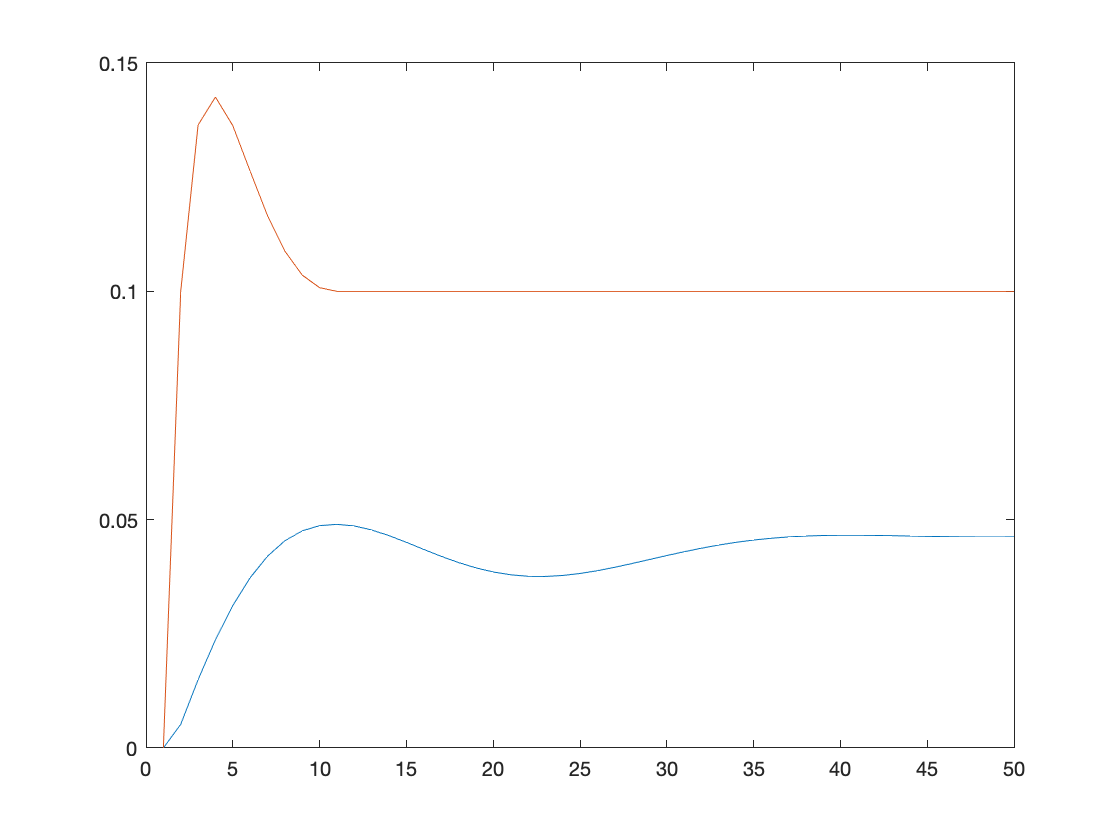

plot(1:Nsimu,Y);

U

U =     1.0166    0.0430    0.0472    0.0530    0.0595    0.0659    0.0723    0.0785    0.0847    0.0907    0.0901    0.0862    0.0855    0.0848    0.0841    0.0833    0.0825    0.0817    0.0808    0.0800    0.0791    0.0783    0.0774    0.0766    0.0758    0.0751    0.0744    0.0738    0.0732    0.0726    0.0721    0.0716    0.0712    0.0708    0.0704    0.0701    0.0698    0.0695    0.0692    0.0689    0.0686    0.0684    0.0681    0.0679    0.0676    0.0674    0.0672    0.0670    0.0667    0.0665
    5.7415    0.1412    0.1549    0.1854    0.2261    0.2705    0.3202    0.3730    0.4231    0.4567    0.4463    0.4229    0.4187    0.4145    0.4104    0.4065    0.4028    0.3992    0.3958    0.3926    0.3894    0.3865    0.3836    0.3809    0.3782    0.3757    0.3733    0.3710    0.3688    0.3667    0.3647    0.3628    0.3609    0.3592    0.3575    0.3559    0.3543    0.3528    0.3514    0.3501    0.3488    0.3476    0.3464    0.3453    0.3442    0.3432    0.3422    0.3413    0.3404    0

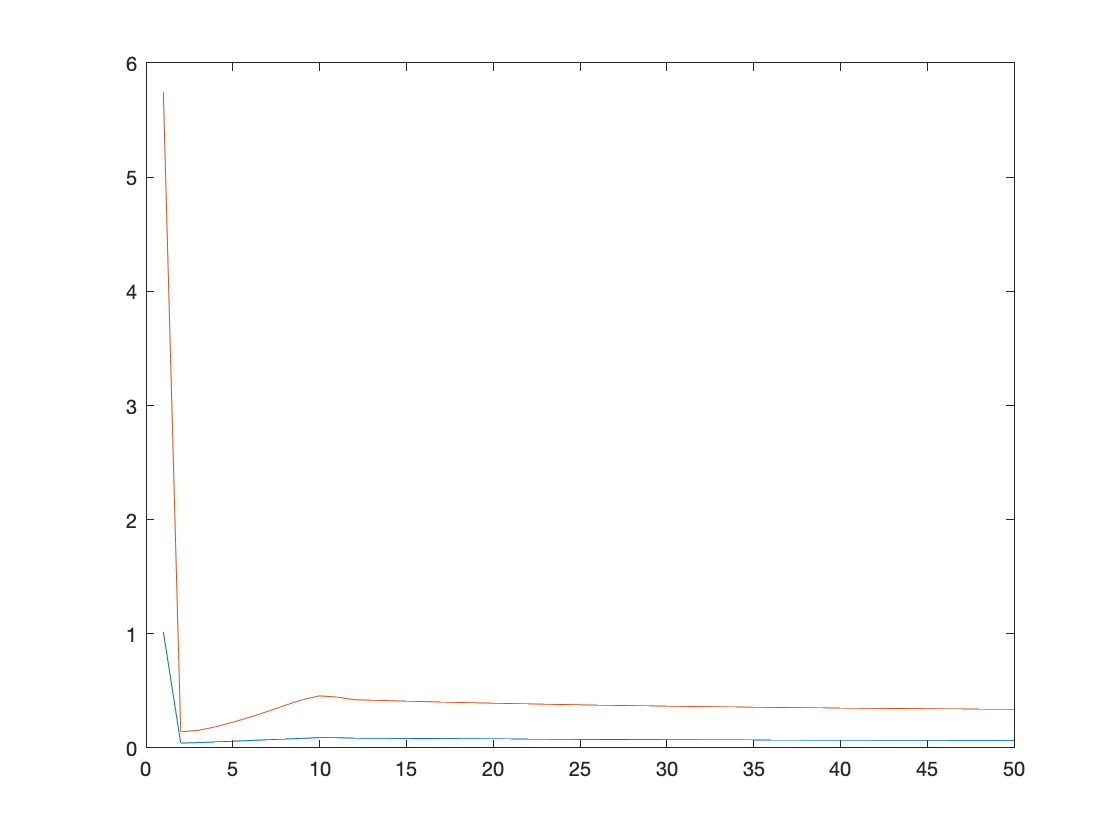

plot(1:Nsimu,U);

Analysis

eigenvalues=eig(A-B*K_Np)

eigenvalues =    0.5075 + 0.0000i
   0.8942 + 0.2047i
   0.8942 - 0.2047i
   0.9754 + 0.0000i
   0.9699 + 0.0000i
   0.9608 + 0.0097i
   0.9608 - 0.0097i
   0.8019 + 0.0000i


modeul = norm(eigenvalues(1),1)

modeul = 0.5075

# Application into Simulink

Ouvrir et compléter le simulink ('2A_SG8_MPC_simu_MPC_student.slx'). 

You must also compile the following two sections for the Simulink file to be executable.

#### Umax prediction generator

Amaxpred=zeros(Np,Np);
Amaxpred(1:Np-1,2:Np)=eye((Np-1));
Bmaxpred=zeros(Np,1);
Bmaxpred(Np,1)=eye(1);
Cmaxpred=eye(Np);
Dmaxpred=zeros(Np,1);

#### Setpoint generator (corresponding to$Tmin(K+1|k)$ and $Dmin(K+1|k)$)

Arefpred=zeros(2*Np,2*Np);
Arefpred(1:2*(Np-1),3:2*Np)=eye(2*(Np-1));
Brefpred=zeros(2*Np,2);
Brefpred(2*(Np-1)+1:2*Np,:)=eye(2);
Crefpred=Arefpred;
Drefpred=Brefpred;

sysrefpred=ss(Arefpred,Brefpred,Crefpred,Drefpred,Te);